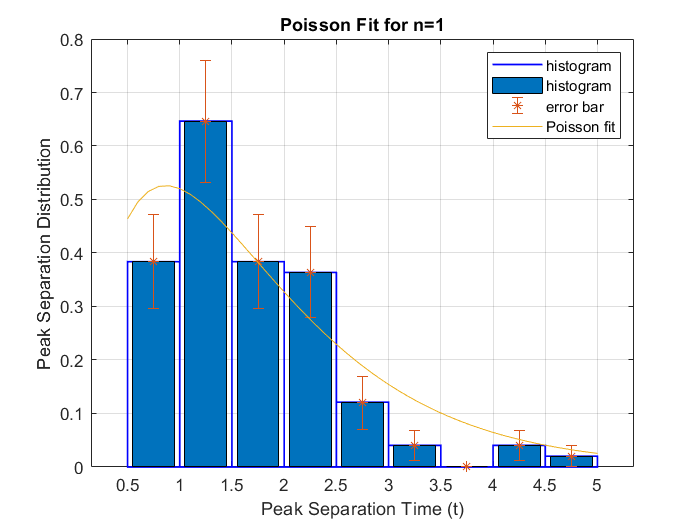

clf;
hold on;
LegHandles = []; LegText = {};


%creating histogram

[CdfF,CdfX] = ecdf(olan1,'Function','cdf');  
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(olan1,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0 0 1],...
    'LineStyle','-', 'LineWidth',1);

%creating error bars

normalizedelements=[0.384 0.646 0.384 0.364 0.12 0.04 0 0.04 0.02];
elements=50*normalizedelements;
bincenters= 0.75:0.5:4.75;
err=sqrt(elements)/50;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'*');
%creating a poisson fit function
%defining A to see exponential on the  graph smoothly.
A=0.5:0.1:5;
b=1.236;
a=1.157;
exp1=b*(a^2)*(A).*exp(-a*A);
plot(A,exp1)


xlabel('Peak Separation Time (t)')
ylabel('Peak Separation Distribution')
title('Poisson Fit for n=1')

%informations about fitted function;
%General model:
 %    f(x) = b*(a^2)*x*exp(-a*x)
%Coefficients (with 68% confidence bounds):
   %    a =       1.157  \mp 0.399
 %      b =       1.236  \mp 0.182

%Goodness of fit:
%  SSE: 0.07073
%  R-square: 0.8312
%  Adjusted R-square: 0.8071
  %RMSE: 0.1005
  

box on
grid on;

legend({'histogram','histogram','error bar','Poisson fit'})